# Problema 2

y = [y1;y2]

f = @(t,y) [(4-2*y(2))/t^3; -exp(y(1))];

t0 = 1;
tf = 2;
h = 0.01;

%y1 en 1
y11 = 0;
%y2 en 2
y22 = 0;


Suponemos una cond. inicial.

y21 = 1;

% y0 = [0;y21];
% 
% [t,y] = ivps(f,t0,tf,y0,h, 5);
% 
% yf = y(:,end);

Utilizando shooting2

Si suponemos y2 en 1 = 1

y21 = 1;
dif = shooting2(f,t0,tf,y11,y21,h,y22)

dif = 1.0295

Si suponemos y2 en 1 = 2

y21 = 2;
dif = shooting2(f,t0,tf,y11,y21,h,y22)

dif = -0.8711

Por lo tanto el valor que buscamos se encuentra entre (1,2).

Con bisección encontramos el valor de y21 tal que y21 = 0.

g = @(y21) shooting2(f,t0,tf,y11,y21,h,y22);
[x, ~] = biseccion(g, 1, 2)

max = 52

x = 1.5000

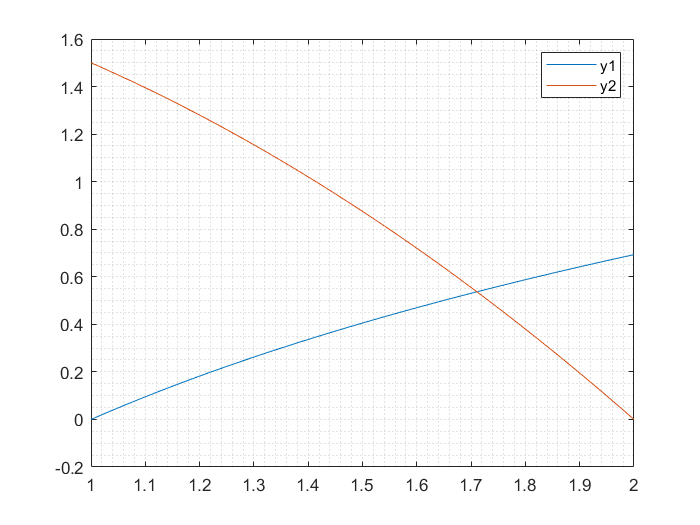

y0 = [0;x];
[t,y] = ivps(f,t0,tf,y0,h, 5);

plot(t,y);
grid minor
legend('y1','y2');